clc
clear all

load("theta_outage.mat")
load("gamma_outage.mat")

theta_outage = theta_outage_for_n;
gamma_outage = gamma_outage_for_n;

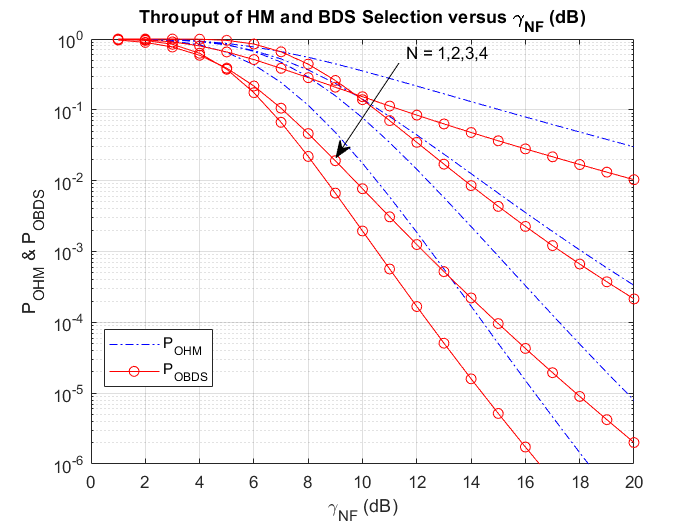

gamma_NF_db = [1:20];
gamma_NF = 10.^(gamma_NF_db/10);

figure
semilogy(gamma_NF_db, gamma_outage, '-.b');
hold on
semilogy(gamma_NF_db, theta_outage, '-or');

legend({'P_{OHM}', '', '', '', 'P_{OBDS}'}, 'Location', 'best')

% h = legend({'P_{OHM}', newline,newline 'P_{OBDS}'});
% set(h,'Interpreter','none')

ylim([1e-6 1])
xlabel('\gamma_{NF} (dB)'); ylabel('P_{OHM} & P_{OBDS}');
title('Throuput of HM and BDS Selection versus \gamma_{NF} (dB)')
grid on, hold on

annotation('textarrow', [0.57,0.48], [0.88,0.7], 'String', 'N = 1,2,3,4', 'LineWidth', 0.1);